clear 
close all
clc


% To fill in right parameters and convert data files to surface height

ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\',rot_rate,freq_value,string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\FFT\\',rot_rate,freq_value,string(ampl_value));

% input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_rot_2.6Hz_9mm_full_plate_separate_frames\Results\';
% output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_rot_2.6Hz_9mm_full_plate\FFT\';


% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_',rot_rate,freq_value,string(ampl_value));

% base_file_name = '20240715_rot_2.6Hz_9mm_full_plate_frame_';


file_extension = 'A_vel_new.dat';

frame_num = 190;
% Construct the file name
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

% Load the data
dr = loadvec(input_file);

% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

% Compute the surface height
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;


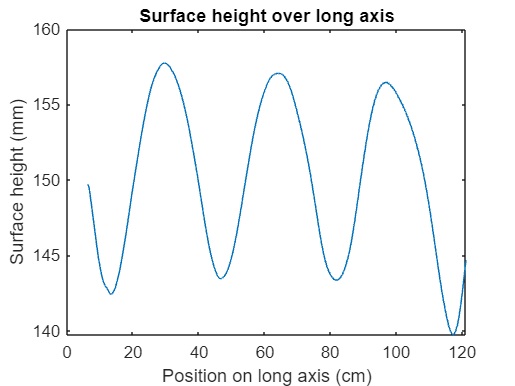

% Plot the amplitude/surface height over the long axis
%ampl = surface_height(30,:,2);
surf_height_long_axis = surface_height(:,30);
ampl_long_axis = surf_height_long_axis - mean(surf_height_long_axis); % is in mm
%ampl = surface_height(30,40,:);
values_long_axis = h.x/10; % in cm
%values_time_axis = start_frame:1:end_frame;
plot(values_long_axis,surf_height_long_axis)
%plot(values_time_axis,ampl)
title('Surface height over long axis')
xlabel('Position on long axis (cm)')
ylabel('Surface height (mm)')
output_file_png_surf_height_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_long_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_surf_height_long);

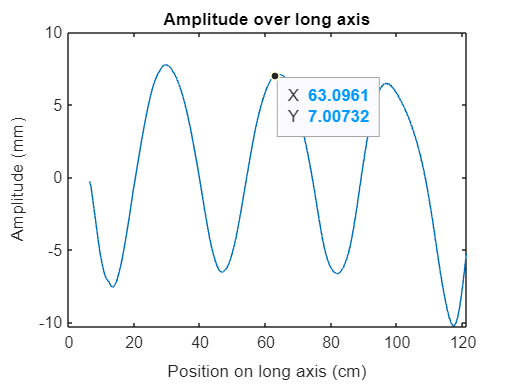

output_file_fig_surf_height_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_long_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_surf_height_long);

L_long_axis = length(surf_height_long_axis);

plot(values_long_axis,ampl_long_axis)
title('Amplitude over long axis')
xlabel('Position on long axis (cm)')
ylabel('Amplitude (mm)')

output_file_png_ampl_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_ampl_long_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_ampl_long);

output_file_fig_ampl_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_ampl_long_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_ampl_long);


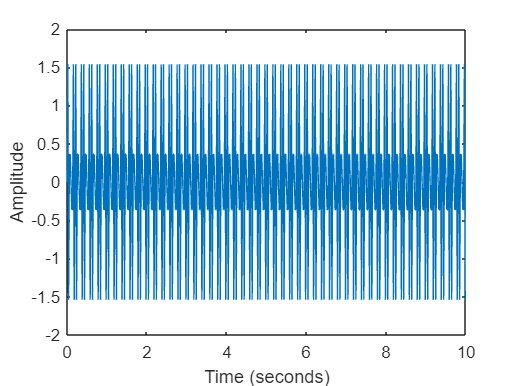

% Example function
Ts = 1/50;
t = 0:Ts:10-Ts;
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')

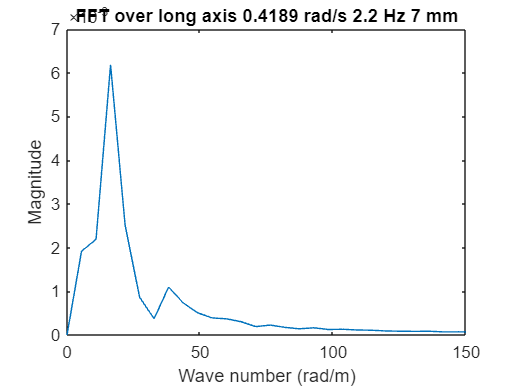

%Fourier over long axis
four_1d_long_axis = fft(ampl_long_axis/1000);
% Distance between points in meters
distance = (h.x(2) - h.x(1)) / 1000; 


%OPTION 1
wave_num_long_axis = 1/distance;
wave_num_four_long_axis = (0:length(four_1d_long_axis)-1)*wave_num_long_axis/length(four_1d_long_axis);

% Plot the Fourier transform against frequencies
plot(wave_num_four_long_axis,2*abs(four_1d_long_axis/L_long_axis))
xlabel('Wave number')
ylabel('Magnitude')
title(sprintf('FFT over long axis %s 2.6Hz %smm',rot_rate,string(ampl_value)))
% xlim([0 30]);
% ylim([0 8]);

% OPTION 2
% % Total physical length along the long axis in meters
% L_physical_long_axis = (max(h.x) - min(h.x)) / 1000;
% 
% % Wave number calculation: k = 2*pi/L_physical_long_axis
% % Here L_physical_long_axis is the total length, and wave_num_long_axis is 2*pi divided by this length
% wave_num_four_long_axis = (0:(L_long_axis - 1)) * (2 * pi / L_physical_long_axis);
% 
% % To get the correct positive/negative wave numbers
% wave_num_four_long_axis = fftshift(wave_num_four_long_axis - pi / distance);
% 
% % Normalize the FFT result
% four_1d_long_axis = fftshift(four_1d_long_axis); % Shift zero frequency to the center
% four_1d_long_axis_magnitude = abs(four_1d_long_axis) / L_long_axis; % Normalized magnitude


% % OPTION 3
% % Total physical length along the long axis in meters
% L_physical_long_axis = distance * L_long_axis; % L_physical_long_axis is the total length in meters
% 
% % Wave number calculation: k = 2*pi/L_physical_long_axis
% wave_num_step = (2 * pi) / L_physical_long_axis; % Step in wave number space
% wave_num_four_long_axis = (0:(L_long_axis/2)) * wave_num_step; % Only positive wave numbers
% 
% % Normalize the FFT result
% four_1d_long_axis_magnitude = abs(four_1d_long_axis(1:L_long_axis/2+1)) / L_long_axis; % Take only the first half
% 
% % PLOT FOR OPTION 2 & 3
% % Plot the Fourier transform against the wave number
% figure;
% plot(wave_num_four_long_axis, 2 * four_1d_long_axis_magnitude)
% xlim([0 150]);
% xlabel('Wave number (rad/m)')
% ylabel('Magnitude')
% title(sprintf('FFT over long axis %s rad/s %s Hz %s mm', rot_rate, freq_value, string(ampl_value)))
% 


% output_file_png_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_long_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_fft_long);

% output_file_fig_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_long_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_fft_long);


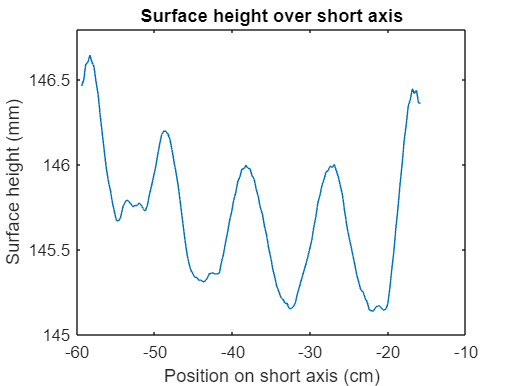

% Surface height on short axis
% Plot the amplitude/surface height over the short axis
surf_height_short_axis = surface_height(170,:);
ampl_short_axis = surf_height_short_axis - mean(surf_height_short_axis);
values_short_axis = h.y/10; % in cm
plot(values_short_axis,surf_height_short_axis)
title('Surface height over short axis')
xlabel('Position on short axis (cm)')
ylabel('Surface height (mm)')

output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_surf_height_short);

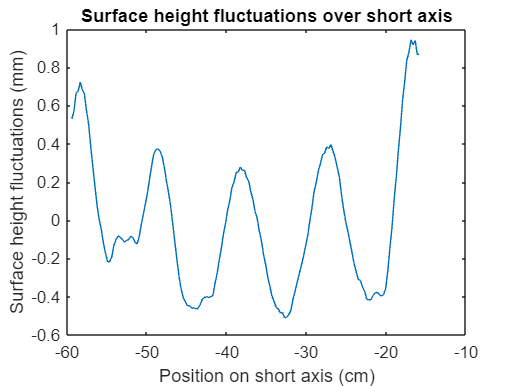

output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_surf_height_short);

% Fit a polynomial (e.g., a linear fit) to the surface height data
p_short_axis = polyfit(values_short_axis, surf_height_short_axis, 1);  % 1 for linear fit

% Calculate the fitted values
fitted_values_short_axis = polyval(p_short_axis, values_short_axis);

% Subtract the fitted values from the original data to obtain the fluctuations
fluctuations_short_axis = surf_height_short_axis - fitted_values_short_axis;

% Plot the fluctuations
figure;
plot(values_short_axis, fluctuations_short_axis);
title('Surface height fluctuations over short axis');
xlabel('Position on short axis (cm)');
ylabel('Surface height fluctuations (mm)');
output_file_png_fluc_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_fluc_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_fluc_short);

output_file_fig_fluc_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_fluc_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_fluc_short);

% 
% % plot(values_short_axis,ampl_short_axis)
% % title('Amplitude over short axis')
% % xlabel('Position on short axis')
% % ylabel('Amplitude')
% 
% 
% L_short_axis = length(fluctuations_short_axis/1000);
% 
% % Compute Fourier transform and rewrite frequency
% 
% %Fourier over short axis
% four_1d_short_axis = fft(fluctuations_short_axis);
% distance_short_axis = (h.y(2)-h.y(1))/1000; % Distance between two values
% freq_short_axis = 1/distance_short_axis; % per meter
% freq_four_short_axis = (0:length(four_1d_short_axis)-1)*freq_short_axis/length(four_1d_short_axis);
% 
% % Plot the Fourier transform against frequencies
% plot(freq_four_short_axis,2*abs(four_1d_short_axis/L_short_axis))
% xlabel('Wave number')
% ylabel('Magnitude')
% title(sprintf('FFT over short axis %s 2.6Hz %smm',rot_rate,string(ampl_value)))
% xlim([0 60]);
% %ylim([0 0.1]);
% output_file_png_fft_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_fft_short);
% output_file_fig_fft_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_fft_short);

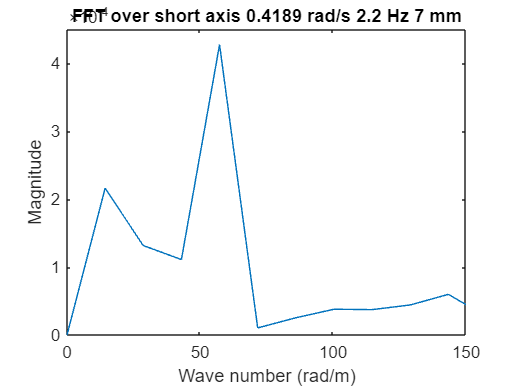

%Fourier over long axis
four_1d_short_axis = fft(fluctuations_short_axis/1000);
% Distance between points in meters
distance = (h.x(2) - h.x(1)) / 1000; 

L_short_axis = length(fluctuations_short_axis/1000);

% OPTION 3
% Total physical length along the long axis in meters
L_physical_short_axis = distance * L_short_axis; % L_physical_long_axis is the total length in meters

% Wave number calculation: k = 2*pi/L_physical_long_axis
wave_num_step_short_axis = (2 * pi) / L_physical_short_axis; % Step in wave number space
wave_num_four_short_axis = (0:(L_short_axis/2)) * wave_num_step_short_axis; % Only positive wave numbers

% Normalize the FFT result
four_1d_short_axis_magnitude = abs(four_1d_short_axis(1:L_short_axis/2+1)) / L_short_axis; % Take only the first half

% PLOT FOR OPTION 2 & 3
% Plot the Fourier transform against the wave number
figure;
plot(wave_num_four_short_axis, 2 * four_1d_short_axis_magnitude)
xlim([0 150]);
xlabel('Wave number (rad/m)')
ylabel('Magnitude')
title(sprintf('FFT over short axis %s rad/s %s Hz %s mm', rot_rate, freq_value, string(ampl_value)))



output_file_png_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_fft_long);

output_file_fig_fft_long = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_FFT_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_fft_long);


% % Performing a 2D Fourier transform on the surface heights 
% four_2d = fft2(surface_height(:,:)-mean(surface_height(:,:)));
% %plot(four_2d)
% imagesc(abs(fftshift(four_2d)));
% 
% xlim([70.0 100.0]);
% ylim([150 290]);

% % Compute frequencies for cross waves
% % ang_freq = 
% % lambda = 2*pi*9.81/(ang_freq^2)
% n = 4
% lambda = 2*0.5/n
% freq = sqrt(9.81/(2*pi*lambda))


% % To make a 3D matrix with all surface heights over space and time
% 
% % Load one file to get the dimensions
% file_name = [base_file_name, '0220', file_extension];
% input_file = fullfile(input_dir, file_name);
% dr = loadvec(input_file);
% % Copy dr to dr_new & delete rows and columns with only zeros
% dr_new = dr;
% dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
% dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
% dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
% dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
% dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
% dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
% h_0 = 150; % surface-pattern distance in mm
% h = surfheight(dr_new, h_0);
% 
% [nx, ny] = size(h.w);
% 
% surface_height_3d = zeros(nx, ny, nt);
% 
% for frame_num = start_frame:end_frame
%     frame_str = sprintf('%04d', frame_num);
%     file_name = [base_file_name, frame_str, file_extension];
%     input_file = fullfile(input_dir, file_name);
% 
%     % Load the data
%     dr = loadvec(input_file);
%     % Copy dr to dr_new & delete rows and columns with only zeros
%     dr_new = dr;
%     dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
%     dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
%     dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
%     dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
%     dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
%     dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
%     h = surfheight(dr_new, h_0);
% 
%     % Store the 2D matrix in the 3D matrix
%     surface_height_3d(:,:,frame_num-start_frame+1) = h.w;
% end
% 